%MA432 Final Project
%Author: Angelo Cicone
clear
clc

## Create data from image

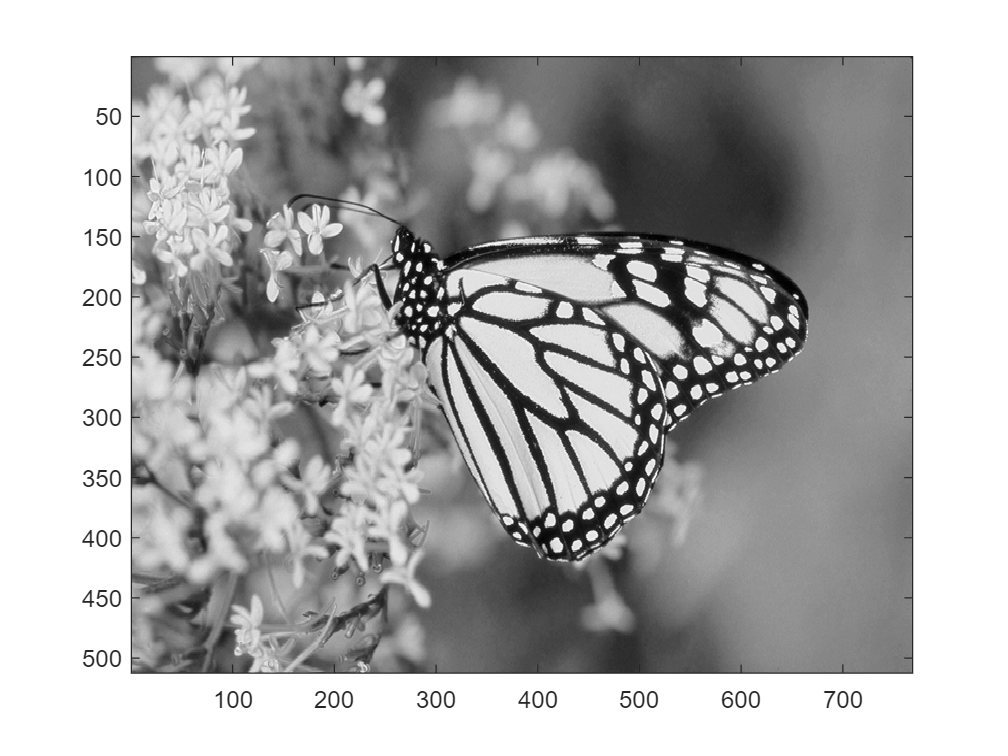

img = imread("monarch.bmp");
img = img(:,:,1);

figure;
imagesc(img)
colormap('gray')

## Use SVD on data

[U, S, Vt] = svd(im2single(img), 'vector');
disp(size(U))

   512   512



disp(size(S))

   512     1



disp(size(Vt))

   768   768



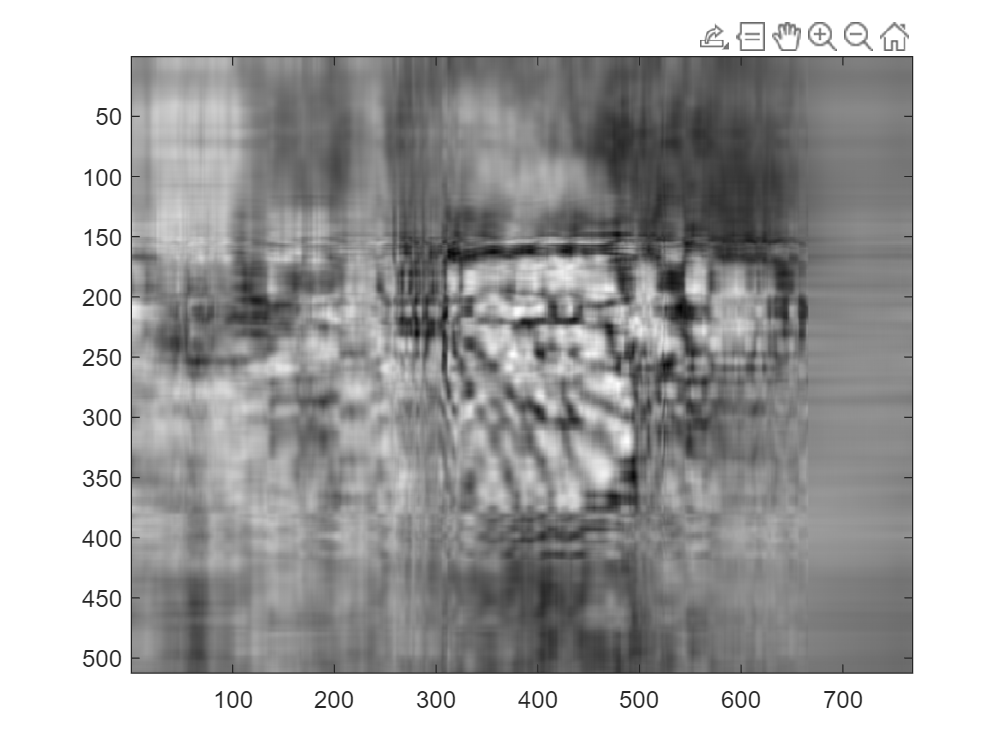


i = 10;
reconstructed_image = U(:,1:i) * diag(S(1:i)) * Vt(:,1:i)';
imagesc(reconstructed_image)
colormap('gray')

## Compress image

i = 25;
%Perform matrix multiplication with more singluar values
fine_reconstructed = U(:,1:i) * diag(S(1:i)) * Vt(:,1:i)'; 
imagesc(fine_reconstructed)
colormap("gray")